# **Planta Sin Control - Bergman Modificado.**

**Elaborado por: **Manuela María Muriel Tobar, David Andrés Ojeda Guzmán

**Universidad de Nariño**

En este trabajo se simula el modelo modificado de Bergman en lazo abierto, se simula 24 horas con resolución de 1 minuto, con tres ingestas de comida (desayuno, almuerzo, cena) y 3 inyecciones de insulina externa antes de cada comida

close all; clear variables; clc;

Se modela el modelo minimo modificado de bergman, modelo matematico usado ampliamente para describir la dinamica glucosa-insulina en pacientes con diabetes mellitus tipo 1

#### **1. Dinamica de la glucosa en la sangre:**


$$\[
\frac{dG(t)}{dt} = - (p_1 + X(t)) \cdot G(t) + p_1 \cdot G_b + D(t)
\]
$$


donde:

- $G(t)
$: Glucosa en sangre en tiempo t [mg/dL] 

- $X(t)
$: Efecto de la insulina activa [1/min]

- $G_b$: Glucosa basal (nivel objetivo o fisiológico) [mg/dL]

-  $D(t)$: Tasa de entrada de glucosa por comida [mg/dL/min]

-  $p_1$: Tasa de eliminación de glucosa independiente de insulina [1/min]

#### **2. Efecto de la insulina activa:**


$$\[
\frac{dX(t)}{dt} = -p_2 \cdot X(t) + p_3 \cdot (I(t) - I_b)
\]
$$


donde: 

- $X(t)$: Insulina activa [1/min]

- $I(t)$: insulina en sangre [mU/dL]

- $I_b
$: insulina basal[mU/dL]

- $p_2$: tasa de disipación del efecto activo [1/min]

- $p_3$: Sensibilidad del cuerpo a la insulina [L/(min^2*mU)]

#### **3. Dinamica de la insulina en sangre**


$$\[
\frac{dI(t)}{dt} = -p_4 \cdot I(t) + \frac{U(t)}{V_I}
\]$$


donde:

- $I(t)$: insulina en sangre [mU/dL]

- $U(t)$: Tasa de administración de insulina exogena [mU/min]

- $V_I$: Volumen de distribución de insulina [L]

- $p_4
$: tasa de eliminación de insulina [1/min]

#### **4. Perturbación por comida**


$$\[
\frac{dD(t)}{dt} = -d_{rate} \cdot D(t)
\]$$


- $D(t)$: Tasa de entrada de glucosa desde el intestino [mg*min/dL]

- $d_{rate}$: tasa de absorción (decaimiento) de la glucosa ingerida [1/min]

#### **5. Glucosa subcutanea**


$$\[
\frac{dG_{sc}(t)}{dt} = \frac{1}{5} \cdot (G(t) - G_{sc}(t))
\]$$


- $G_{sc}(t)$: Glucosa en el tejido subcutaneo [mg/dL]

- $G(t)$: Glucosa en sangre [mg/dL]

[p1, p2, p3, p4, Gb, Ib, VI, G0, X0, I0, D0, Gsc0] = configurar_parametros();

%% 2. Definición de insulina y comidas
horas_comidas = [7*60, 13*60, 20*60]; % 7am, 1pm, 8pm (en minutos)

D = @(t) definir_D_multi_mejorado(t, ...
    [40, horas_comidas(1), 90], ...   % Desayuno: 45g CHO, 90min absorción
    [60, horas_comidas(2), 120], ...  % Almuerzo: 80g CHO, 120min absorción
    [50, horas_comidas(3), 90]);      % Cena: 60g CHO, 90min absorción

la funcion $D(t)$ define la tasa de entrada de glucosa a la sangre debido a multiples comidas, esta entrada no es instantanea, sino que  sigue una curva donde

-  Primero aumenta (fase de absorción)

- Luego alcanza un pico

- Y despues disminuye a medida que se completa la digestión

Para comida $i
$


$$\[
D_i(t) = \begin{cases}
    \frac{1000 \cdot C_i}{d_i} \cdot \left( \frac{\tau_i^2 \cdot e^{-2\tau_i}}{0.07} \right) \cdot 10 & \text{si } t_i \leq t \leq t_i + d_i \\
    0 & \text{en otro caso}
\end{cases}
\]
\[
\tau_i = \frac{t - t_i}{d_i}
\]
$$


donde sus componentes son:

- $C_i
$: gramos de carbohidratos ingeridos

- $d_i
$: Duración de la absorción (en minutos)

- $\tau_i = \frac{t - t_i}{d_i}$ : Tiempo normalizado dentro del intervalo de absorción

U = @(t) definir_U_multi_mejorado(t, ...
    [4, 8*60, 180], ...   % 8:00 am
    [4, 13*60, 180], ...  % 1:00 pm
     [5, 20*60, 180]);     % 8:00 pm

$U(t)$ se modela como la absorción en sangre de insulina exogena tras una inyección, esta se inyecta en el tejido subcutaneo y luego

- Se absorbe gradualmente

- Alcanza un pico maximo de acción

- finalmente disminuye (se elimina del cuerpo)

Para cada dosis $i$:


$$\[
U_i(t) = \begin{cases}
    A_i \cdot \left( \frac{\tau_i^{1.5} \cdot e^{-2\tau_i}}{0.2} \right) & \text{si } t \geq t_i \\
    0 & \text{si } t < t_i
\end{cases}
\quad \text{con } \tau_i = \frac{t - t_i}{d_i}
\]$$


donde sus componentes son:

$A_i
$: Dosis de insulina administrada

$t_i$: tiempo en el que se aplica la dosis

$d_i$: duración esperada del efecto

$\tau_i$: tiempo desde la inyección, normalizado

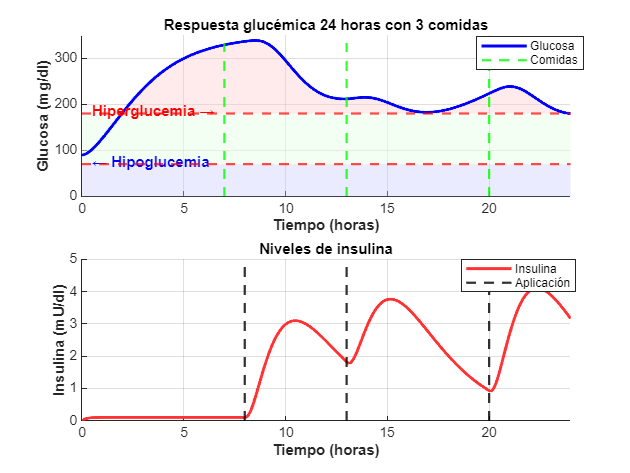

tspan = 0:1:24*60; % 24 horas en minutos
y0 = [G0; X0; I0; D0; Gsc0];

[t_sim, Y_sim] = ode45(@(t,y) modelo_minimo(t, y, p1, p2, p3, p4, Gb, Ib, VI, U, D), ...
    tspan, y0);

G = Y_sim(:,1);
I = Y_sim(:,3);

figure('Color','w');

% ===== Glucosa en sangre =====
subplot(2,1,1);
hold on;

% Área segura (70-180 mg/dl)
fill([t_sim/60; flipud(t_sim/60)], ...
     [70*ones(size(t_sim)); flipud(180*ones(size(t_sim)))], ...
     [0.9 1 0.9], 'EdgeColor', 'none', 'FaceAlpha', 0.5);

% Área de hipoglucemia (<70)
fill([t_sim/60; flipud(t_sim/60)], ...
     [zeros(size(t_sim)); flipud(min(G,70))], ...
     [0.8 0.8 1], 'EdgeColor', 'none', 'FaceAlpha', 0.4);

% Área de hiperglucemia (>180)
fill([t_sim/60; flipud(t_sim/60)], ...
     [180*ones(size(t_sim)); flipud(max(G,180))], ...
     [1 0.8 0.8], 'EdgeColor', 'none', 'FaceAlpha', 0.4);

% Curva de glucosa
h1 = plot(t_sim/60, G, 'b', 'LineWidth', 2);

% Umbrales
yline(70, '--r', 'LineWidth', 1.5, 'Alpha', 0.7);
yline(180, '--r', 'LineWidth', 1.5, 'Alpha', 0.7);

text(0.5, 75, '← Hipoglucemia', 'Color', 'blue', 'FontWeight','bold');
text(0.5, 185, 'Hiperglucemia →', 'Color', 'red', 'FontWeight','bold', 'HorizontalAlignment','left');

% Líneas verticales de comidas
for t_comida = horas_comidas/60
    h2 = xline(t_comida, '--g', 'LineWidth', 1.5, 'Alpha', 0.8);
end

xlabel('Tiempo (horas)', 'FontWeight','bold');
ylabel('Glucosa (mg/dl)', 'FontWeight','bold');
title('Respuesta glucémica 24 horas con 3 comidas', 'FontWeight','bold');
xlim([0 24]);
ylim([0 350]);
grid on;

% Leyenda: solo glucosa y comidas
legend([h1 h2], {'Glucosa', 'Comidas'}, 'Location','northeastoutside',"Position", [0.7576 0.8540 0.1679, 0.0679]);

% ===== Insulina =====
subplot(2,1,2);
hold on;
plot(t_sim/60, I, 'Color',[1 0.2 0.2], 'LineWidth', 2);

% Líneas verticales de aplicación de insulina
momentos_insulina = [8.0, 13.0, 20.0]; % en horas
for t_ins = momentos_insulina
    xline(t_ins, '--k', 'LineWidth', 1.5, 'Alpha', 0.8);
end

xlabel('Tiempo (horas)', 'FontWeight','bold');
ylabel('Insulina (mU/dl)', 'FontWeight','bold');
title('Niveles de insulina', 'FontWeight','bold');
xlim([0 24]);
grid on;
legend({'Insulina', 'Aplicación'}, 'Location','northeastoutside', "Position", [0.7333 0.3836 0.1804, 0.0679]);

function [p1, p2, p3, p4, Gb, Ib, VI, G0, X0, I0, D0, Gsc0] = configurar_parametros()
    p1 = 0.03;
    p2 = 0.02;
    p3 = 4.5e-5;
    p4 = 0.08;
    Gb = 90;
    Ib = 10;
    VI = 12;
    G0 = Gb;
    X0 = 0;
    I0 = 0;
    D0 = 0;
    Gsc0 = G0;
end

function D = definir_D_multi_mejorado(t, varargin)
    D = 0;
    for i = 1:size(varargin,2)
        carga = varargin{i}(1)*1000;
        t_ini = varargin{i}(2);
        dur = varargin{i}(3);

        if t >= t_ini && t <= t_ini + dur
            tau = (t - t_ini)/dur;
            absorcion = carga * (tau.^2) .* exp(-2*tau) / 0.07;
            D = D + absorcion/dur*10;
        end
    end
end

function U = definir_U_multi_mejorado(t, varargin)
    U = 0;
    for i = 1:size(varargin,2)
        dosis = varargin{i}(1);
        t_ini = varargin{i}(2);
        dur = varargin{i}(3);

        if t >= t_ini
            tau = (t - t_ini)/dur;
            U = U + dosis * (tau.^1.5) .* exp(-2*tau) / 0.2;
        end
    end

    U = U + 0.1;
end

function dydt = modelo_minimo(t, y, p1, p2, p3, p4, Gb, Ib, VI, U, D)
    G = y(1); X = y(2); I = y(3); Dt = y(4); Gsc = y(5);
    dGdt = -(p1 + X)*G + p1*Gb + Dt;
    dXdt = -p2*X + p3*(I - Ib);
    dIdt = -p4*I + U(t)/VI;
    dDdt = -5*Dt;
    dGscdt = (1/5)*(G - Gsc);
    dydt = [dGdt; dXdt; dIdt; dDdt; dGscdt];
end

### Conclusiones:

La gráfica muestra la evolución de la glucosa e insulina a lo largo de 24 horas en un paciente con diabetes tipo 1 que recibe tres comidas diarias y tres aplicaciones de insulina rápida. Se observa un claro aumento de glucosa posterior a cada comida, con picos alrededor de las 8 am, 1 pm y 8 pm. Aunque las inyecciones de insulina coinciden en tiempo con las comidas y logran atenuar parcialmente la hiperglucemia, los niveles de glucosa se mantienen por encima del rango óptimo (70–180 mg/dL) durante gran parte del día, especialmente después del almuerzo, lo que indica que la dosis o el momento de aplicación podría no ser suficiente para controlar adecuadamente la respuesta glucémica.

Las curvas reflejan una absorción y acción transitoria. En conjunto, los resultados sugieren que el esquema actual logra cierta modulación glucémica, pero no previene episodios de hiperglucemia sostenida.